Problem 1: Scale Invariant Feature Transform (SIFT) Select some interesting images with multiple objects (or use the images supplied with the lab). Generate additional images from the given images under some 1) scale, 2) rotation/pose, 3) illumination, and 4) partial occlusion variations. Use SIFT transform to (a) Compute interesting robust features, and (b) Use them for matching with images under (i) scale, (ii) rotation/pose, (iii) illumination, and (iv) partial occlusion variations. Comment on the quality of results (successful matches) and computation time. When does this algorithm fail?

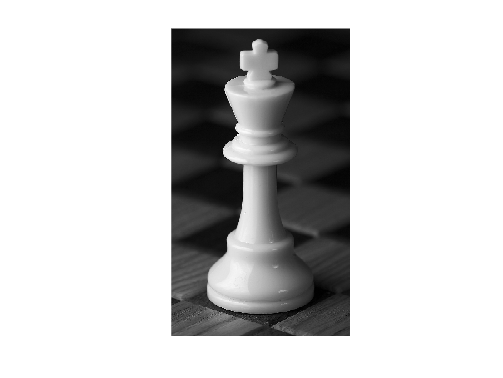

close all
clear all
clc
path = "/MATLAB Drive/EE146Lab8/Lab8/king.jpg";
img = im2gray(imread(path));
imshow(img)


Time taken for Pyramid level generation is :16.922165

Time taken for finding the key points is :10.099543


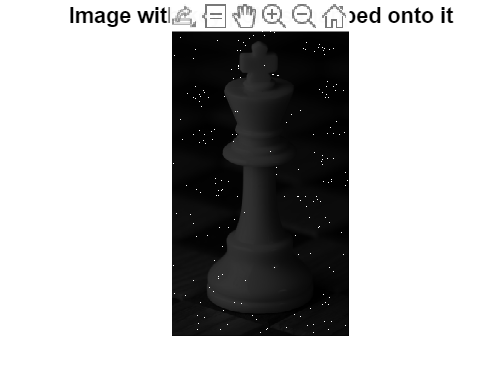


Time taken for magnitude and orientation assignment is :11.528891

Time taken for finding key point desctiptors is :14.724194


img_scaled = imresize(img, 0.5);
img_rot = imrotate(img,45);
img_ill = imadjust(img);
img_occ = img;
y_start = (size(img,1)/2);
y_end = size(img,1);
x_start = 1;
x_end = size(img,2)/2;
img_occ(y_start:y_end, x_start:x_end) = 0;
%imshow(img_occ)

[kpd_one, kploc_one] = SIFT(img);


Time taken for Pyramid level generation is :16.704469

Time taken for finding the key points is :10.883533


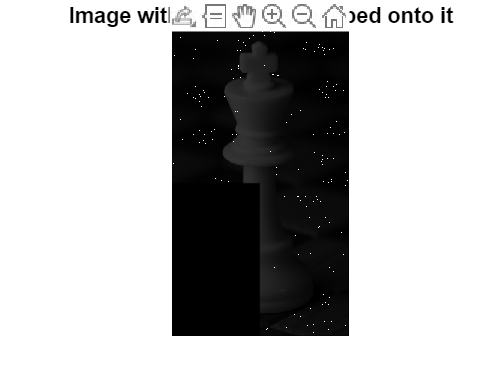


Time taken for magnitude and orientation assignment is :12.368227

Time taken for finding key point desctiptors is :14.607003


[kpd_two, kploc_two] = SIFT(img_occ);

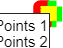

% [kpd_two, kploc_two] = SIFT(img_scaled);
% m_three = SIFT(img_rot);
% m_four = SIFT(img_occ);

m = matchFeatures(kpd_one, kpd_two);
m_one = kploc_one(m(:,1), :);
m_two = kploc_two(m(:,2), :);

figure;

title("SIFT Matched Points")
showMatchedFeatures(img, img_occ, m_one, m_two, "montag");
legend("Matched Points 1", "Matched Points 2");